# Chapter 4, Section 3 (Part 2)

Now we are going to prove a theorem that we wish we had when reading the author's discussion of the inverse of a coordinate transformation matrix on page 181 of our textbook. First, let's recall a theorem we have already proved (Theorem 4 of section 4.2, page 217).

# Theorem

Let $V$ and $W$ be finite dimensional vector spaces and let $B=\{\vec v_1,\ \ldots,\ \vec v_n\}$ be a basis for $V$. If $T:\, V\rightarrow W$ is a linear transformation, then  $R(T)=\text{span}\{T(\vec v_1),\ \ldots,\ T(\vec v_n)\}$.

Now we will add an additional assumption, that the linear transformation $T:\, V\rightarrow W$ is one-to-one.

# Theorem

Let $V$ and $W$ be finite dimensional vector spaces and let $B=\{\vec v_1,\ \ldots,\ \vec v_n\}$ be a basis for $V$. If $T:\, V\rightarrow W$ is a one-to-one linear transformation, then $\{T(\vec v_1),\ \ldots,\ T(\vec v_n)\}$ is a basis for $R(T)$.

**Proof:** We know that $R(T)=\text{span}\{T(\vec v_1),\ \ldots,\ T(\vec v_n)\}$. To show that it is a basis, we need only show that the vectors $T(\vec v_1),\ \ldots,\ T(\vec v_n)$ are linearly independent. Assume that:


$$c_1T(\vec v_1)+\cdots+c_n T(\vec v_n)=\vec 0$$


Using the properties $T(\vec u+\vec v)=T(\vec u)+T(\vec v)$ and $T(c\vec u)=cT(\vec u)$, we can write:


$$T(c_1\vec v_1+\cdots+c_n\vec v_n)=\vec 0$$


Because $T(\vec 0)=\vec 0$, we can write:


$$T(c_1\vec v_1+\cdots+c_n\vec v_n)=T(\vec 0)$$


Because $T$ is one-to-one, we know that $T(\vec u)=T(\vec v)$ implies that $\vec u=\vec v$, so:


$$c_1\vec v_1+\cdots+c_n\vec v_n=\vec 0$$


Since $B=\{\vec v_1,\ \ldots,\ \vec v_n\}$ is a basis for $V$, these vectors are linearly independent, so $c_1=0,\ \ldots,\ c_n=0$. Therefore, the only linear combination


$$c_1T(\vec v_1)+\cdots+c_n T(\vec v_n)=\vec 0$$


is the trivial combination (all the constants are zero). Therefore, $T(\vec v_1),\ \ldots,\ T(\vec v_n)$ are linearly independent and 


$$B_{R(T)}=\{T(\vec v_1),\ \ldots,\ T(\vec v_n)\}$$


is a basis for $R(T)$.

# Example #1

Let $T:\, \mathbb R^2\rightarrow \mathbb R^2$ be defined by


$$T\left(\pmatrix{x\cr y}\right)=\pmatrix{2x+4y\cr 3x+6y}$$


Determine whether $\{T(\vec e_1),\ T(\vec e_2)\}$ is a basis for $\mathbb R^2$.

**Solution:** Recall that $\vec e_1$ and $\vec e_2$ are the first and second columns of the $2\times 2$ identity matrix and $B=\{\vec e_1,\, \vec e_2\}$ is called the standard basis for $\mathbb R^2$. However,


$$T(\vec e_1)=T\left(\pmatrix{1\cr 0}\right)=\pmatrix{2(1)+4(0)\cr 3(1)+6(0)}=\pmatrix{2\cr 3}$$


and


$$T(\vec e_2)=T\left(\pmatrix{0\cr 1}\right)=\pmatrix{2(0)+4(1)\cr 3(0)+6(1)}=\pmatrix{4\cr 6}$$


We can check these calculations with an anonymous function.

T=@(x,y) [2*x+4*y;3*x+6*y];
T(1,0)

ans =      2
     3


T(0,1)

ans =      4
     6


Note that $T(0,1)=2T(1,0)$, so $T(\vec e_1)$ and $T(\vec e_2)$ are linearly dependent, so $\{T(\vec e_1),\, T(\vec e_2)\}$ is **not** a basis for $\mathbb R^2$.  We can visualize this.

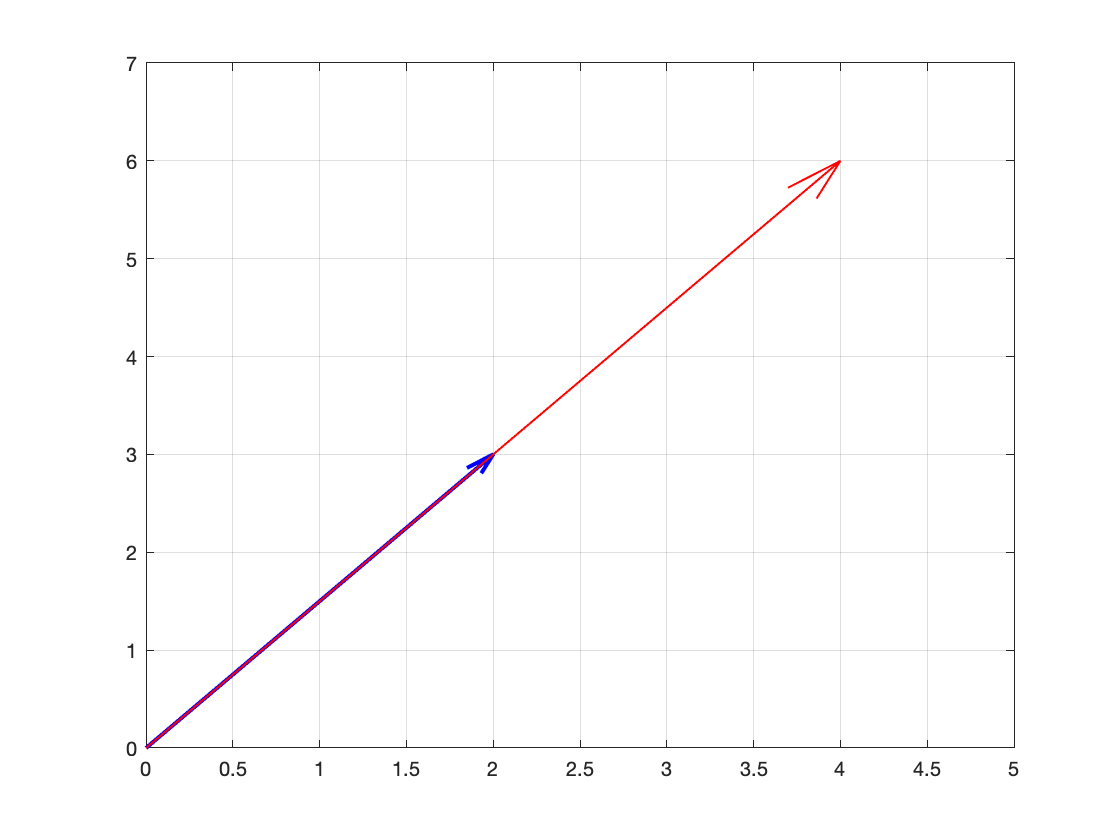

figure
quiver(0,0,2,3,0,'LineWidth',2,'Color','b')
hold on
quiver(0,0,4,6,0,'LineWidth',1,'Color','r')
grid on
axis([0,5,0,7])
hold off

They are parallel, so linearly dependent.

# Example #2

Let $T:\, \mathbb R^3\rightarrow \mathbb R^3$ be defined by


$$T\left(\pmatrix{x\cr y\cr z}\right)=\pmatrix{x-y+2z\cr x+2z\cr y+z}$$


Determine whether $\{T(\vec e_1),\ T(\vec e_2),\ T(\vec e_3)\}$ is a basis for $\mathbb R^3$.

**Solution:** Note that


$$T\left(\pmatrix{1\cr 0\cr 0}\right)=\pmatrix{1\cr 1\cr 0}$$


and


$$T\left(\pmatrix{0\cr 1\cr 0}\right)=\pmatrix{-1\cr 0\cr 1}$$


and:


$$T\left(\pmatrix{0\cr 0\cr 1}\right)=\pmatrix{2\cr 2\cr 1}$$


We can check this with Matlab.

T=@(x,y,z) [x-y+2*z;x+2*z;y+z];
T(1,0,0)

ans =      1
     1
     0


T(0,1,0)

ans =     -1
     0
     1


T(0,0,1)

ans =      2
     2
     1


Same answers. Now, are they linearly independent? Let's enter each as a column to form the following matrix 


$$\pmatrix{1 & -1 & 2\cr 1 & 0 & 2\cr 0 & 1 & 1}$$


Recall that if the determinant of this matrix is not zero, then the columns are linearly independent (not the only way to show they are linearly independent). We use the cofactor expansion across the third row.


$$\begin{array}{rcl}
\left|\matrix{1 & -1 & 2\cr 1 & 0 & 2\cr 0 & 1 & 1}\right|&=&0\left|\matrix{-1 & 2\cr 0 & 2}\right|-1\left|\matrix{1 & 2\cr 1 & 2}\right|+1\left|\matrix{1 & -1\cr 1 & 0}\right|\\
&=&0(-2)-1(0)+1(1)\\
&=&1
\end{array}$$


We can check this with Matlab.

A=[1 -1 2;1 0 2;0 1 1];
det(A)

ans = 1

Same answer, so they are linearly independent. By our theorems above, we have three vectors $T(\vec e_1)$, $T(\vec e_2)$, $T(\vec e_3)$ that are also in $\mathbb R^3$, so $\{T(\vec e_1),\ T(\vec e_2),\ T(\vec e_3)\}$ is a basis for $\mathbb R^3$. We can visualize this.

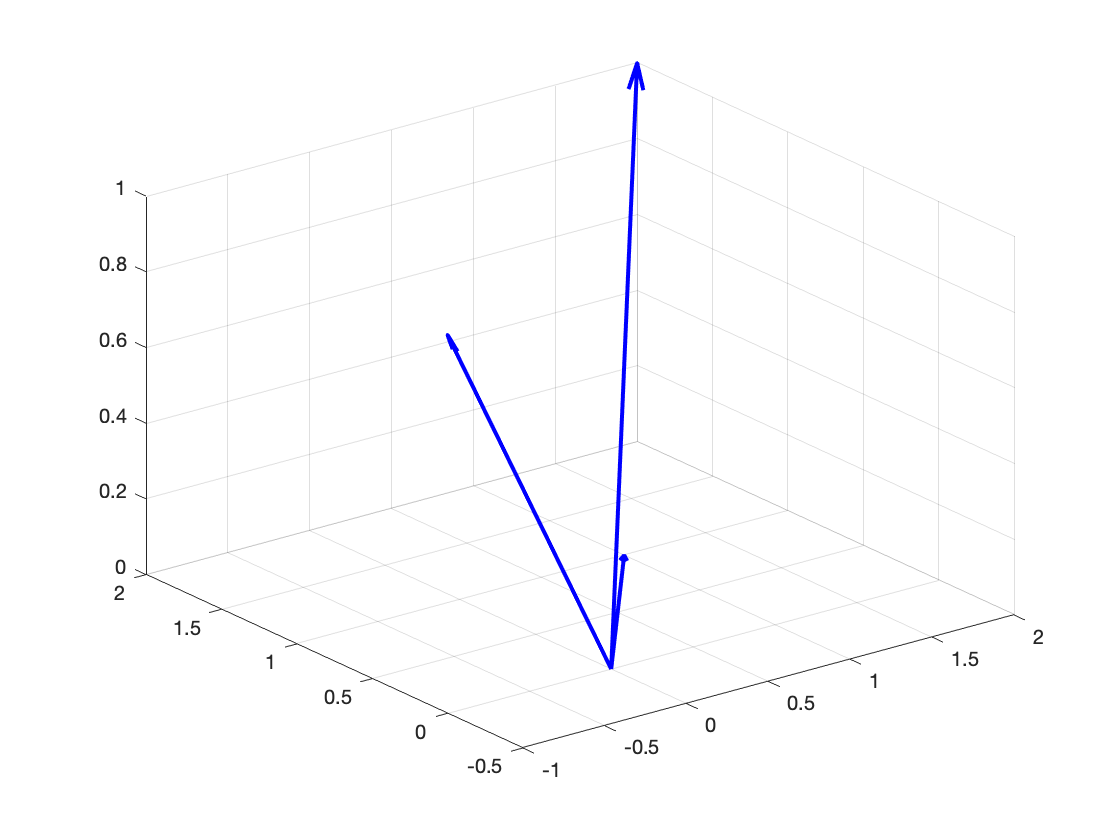

figure
quiver3(0,0,0,1,1,0,0,'LineWidth',2,'Color','b')
hold on
quiver3(0,0,0,-1,0,1,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,2,2,1,0,'LineWidth',2,'Color','b')
grid on

We can rotate this image and note that when we draw a plane containing any two of the vectors, the third vector does not lie in their plane, so it cannot be written as a linear combination of the two that lie in the plane.

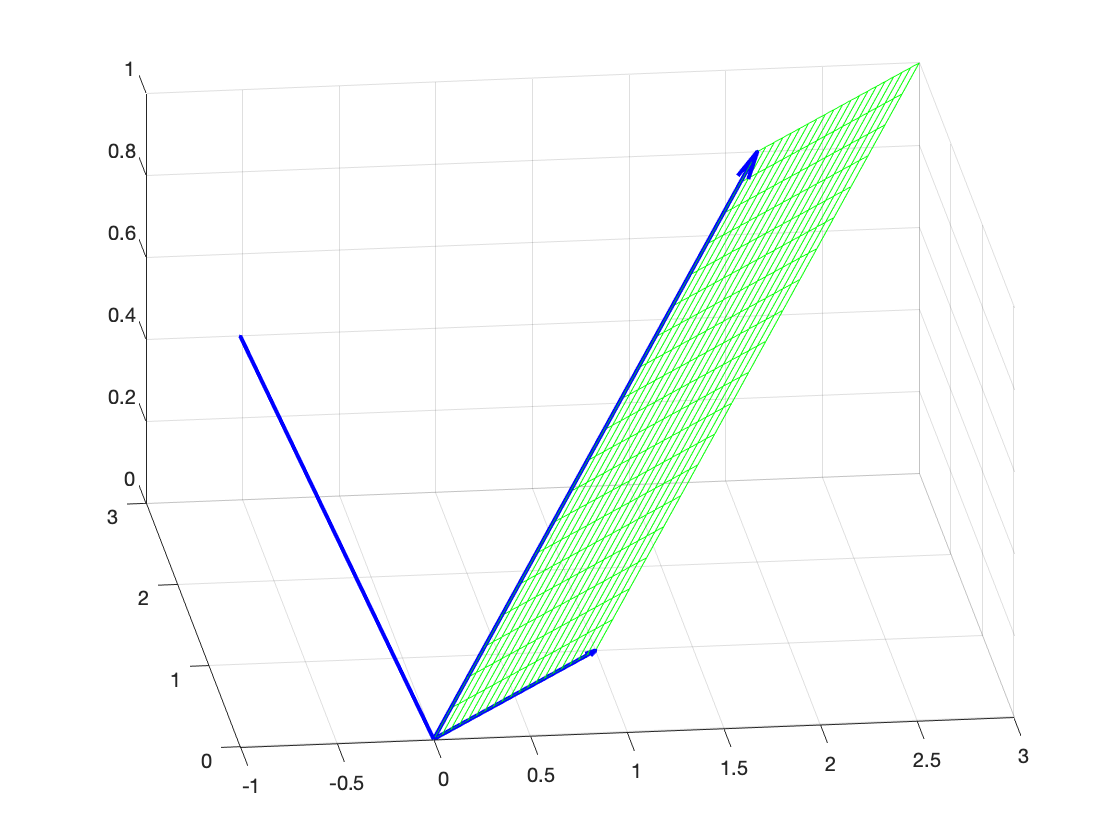

figure
quiver3(0,0,0,1,1,0,0,'LineWidth',2,'Color','b')
hold on
quiver3(0,0,0,-1,0,1,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,2,2,1,0,'LineWidth',2,'Color','b')
s=linspace(0,1,20);
t=linspace(0,1,20);
[S,T]=meshgrid(s,t);
X=S+2*T;
Y=S+2*T;
Z=T;
mesh(X,Y,Z,'EdgeColor','g','FaceColor','none')
grid on
view(-7,31)
hold off

We have clear visual evidence that the vectors are linearly independent, because no vector in the set can be written as a linear combination of the others.

# Isomorphism

We can now define what is known as an isomorphism.

**Definition:** Let $V$ and $W$ be vector spaces. A linear transformation $T:\, V\rightarrow W$ that is one-to-one and onto is called an **isomorphism**. In this case the vector spaces $V$ and $W$ are called isomorphic spaces.

# Example #3

Define $T:M_{2\times 2}\rightarrow M_{2\times 2}$ by $T(A)=\pmatrix{1 & 2\cr 1 & 0}A-A\pmatrix{1 & 2\cr 1 & 0}$.

- Show that $T$ is a linear transformation.

- Is $T$ an isomorphism?

**Solution:**

**Part 1:** Let $A, B\in M_{2\times 2}$. Then,


$$\begin{array}{rcl}
T(A+B)&=&\pmatrix{1 & 2\cr 1 & 0}(A+B)-(A+B)\pmatrix{1 & 2\cr 1 & 0}\\
&=&\pmatrix{1 & 2\cr 2 & 0}A+\pmatrix{1 & 2\cr 2 & 0}B-A\pmatrix{1 & 2\cr 2 & 0}-B\pmatrix{1 & 2\cr 2 & 0}\\
&=&\left(\pmatrix{1 & 2\cr 2 & 0}A-A\pmatrix{1 & 2\cr 2 & 0}\right)+\left(\pmatrix{1 & 2\cr 2 & 0}B-B\pmatrix{1 & 2\cr 2 & 0}\right)\\
&=&T(A+B)
\end{array}$$


Next, let $c\in R$. Then,


$$\begin{array}{rcl}
T(cA)&=&\pmatrix{1 & 2\cr 2 & 0}(cA)-(cA)\pmatrix{1 & 2\cr 2 & 0}\\
&=&c\left(\pmatrix{1 & 2\cr 2 & 0}A\right)-c\left(A\pmatrix{1 & 2\cr 2 & 0}\right)\\
&=&c\left(\pmatrix{1 & 2\cr 2 & 0}A-A\pmatrix{1 & 2\cr 2 & 0}\right)\\
&=&cT(A)
\end{array}$$


Therefore, $T$ is a linear transformation. Now, is it an isomorphism? Is it one-to-one? Let's check the nullspace of $T$. Let $A\in N(T)$. Then,


$$\begin{array}{rcl}
T(A)&=&0\\
\pmatrix{1 & 2\cr 2 & 0}A-A\pmatrix{1 & 2\cr 2 & 0}&=&\pmatrix{0&0\cr 0 & 0}\\
\pmatrix{1 & 2\cr 2 & 0}A&=&A\pmatrix{1 & 2\cr 2 & 0}
\end{array}$$


Therefore, the nullspace of $T$ is all matrices that commute with $\pmatrix{1 & 2\cr 2 & 0}$. How about the identity matrix?


$$\pmatrix{1 & 2\cr 2 & 0}\pmatrix{1 & 0\cr 0 & 1}=\pmatrix{1 & 0\cr 0 & 1}\pmatrix{1 & 2\cr 2 & 0}$$


Therefore, $\pmatrix{1 & 0\cr 0 & 1}\in N(T)$, so $N(T)\ne \{0\}$, so this linear transformation is not one-to-one. Therefore, it is **not** an isomorphism.

# Example #4

Define $T:M_{2\times 2}\rightarrow P_3$ by $T\left(\pmatrix{a & b\cr c & d}\right)=a+bx+cx^2+dx^3$.  Is this an isomorphism?

**Solution:** Let $A, B\in M_{2\times 2}$. Then,


$$\begin{array}{rcl}
T(A+B)&=&T\left(\pmatrix{a & b\cr c & d}+\pmatrix{e & f\cr g & h}\right)\\
&=&T\left(\pmatrix{a+e & b+f\cr c+g & d+h}\right)\\
&=&(a+e)+(b+f)x+(c+g)x^2+(d+h)x^3\\
&=&(a+bx+cx^2+dx^3)+(e+fx+gx^2+hx^3)\\
&=&T\left(\pmatrix{a & b\cr c & d}\right)+T\left(\pmatrix{e & f\cr g & h}\right)\\
&=&T(A)+T(B)
\end{array}$$


Next, let $r\in \mathbb R$. Then,


$$\begin{array}{rcl}
T(rA)&=&T\left(r\pmatrix{a & b\cr c & d}\right)\\
&=&T\left(\pmatrix{ra & rb\cr rc & rd}\right)\\
&=&(ra)+(rb)x+(rc)x^2+(rd)x^3\\
&=&r(a+bx+cx^2+dx^3)\\
&=&rT\left(\pmatrix{a & b\cr c & d}\right)\\
&=&rT(A)
\end{array}$$


Therefore, $T$ is a linear transformation. Is it one-to-one? Let's check the nullspace. Let $A=\pmatrix{a & b\cr c & d}$ be an element of $N(T)$, then


$$\begin{array}{rcl}
T(A)&=&0\\
T\left(\pmatrix{a & b\cr c& d}\right)&=&0\\
a+bx+cx^2+dx^3&=&0+0x+0x^2+0x^3\\
\end{array}$$


Comparing coefficients, this implies that $a=b=c=d=0$,  so $A=\pmatrix{0 & 0\cr 0 & 0}$. Therefore, $N(T)=\{0\}$, which means that $T$ is one-to-one. Now, is it onto? Let $p(x)=a+bx+cx^2+dx^3\in P_3$. Then, $\pmatrix{a & b\cr c & d}\in M_{2\times 2$ and


$$T\left(\pmatrix{a & b\cr c & d}\right)=a+bx+cx^2+dx^3$$


Because we have shown that for any polynomial $p(x)\in P_3$ there exists a matrix $A\in M_{2\times 2}$ such that $T(A)=p(x)$, we've shown that $T$ in onto $P_3$. Therefore, $T$ is an isomorphism. This means that the vector spaces $M_{2\times 2}$ and $P_3$ are isomorphic.

# Theorem

Let $A$ be an $n\times n$ matrix and $T:\mathbb R^n\rightarrow \mathbb R^n$ be the mapping defined by $T(\vec x)=A\vec x$. Then $T$ is an isomorphism if and only if $A$ is invertible.

**Proof:** We have an "if and only if" statement to prove, which means we have two things we need to prove:

- If $T$ is an isomorphism, then $A$ is invertible.

- If $A$ is invertible, then $T$ is an isomorphism.

**Part 1:** Assume that $T$ is an isomorphism. Then  $T$ is linear transformation that is lone-to-one and onto $\mathbb R^n$. Let $B=\{\vec e_1,\ \ldots,\ \vec e_n\}$ be a basis for $\mathbb R^n$. Then $\left\{T(\vec e_1),\ \ldots,\ T(\vec e_n)\right\}$ is a basis for the range of $T$. Let's examine $T(\vec e_1)$ to make things clear.


$$\begin{array}{rcl}
T(\vec e_1)&=&A\vec e_1\\
&=&\pmatrix{a_{11} & a_{12}& \cdots & a_{1n}\cr a_{21} & a_{22} & \cdots & a_{2n}\cr \vdots & \vdots & \vdots & \vdots\cr a_{n1} & a_{n2} & \cdots & v_{nn} }\pmatrix{1\cr 0\cr \vdots\cr 0}\\
&=&\pmatrix{a_{11}\cr a_{21}\cr \vdots\cr a_{n1}}
\end{array}$$


To perform this multiplication, we will use our method for multiplying a matrix times a vector. We multiply 1 times the first column, plus 0 times the second column, ..., plus 0 times the $n$th column. So this just gives us the first column of matrix $A$. Let's examine $T(\vec e_2)$ to make this even more clear.


$$\begin{array}{rcl}
T(\vec e_2)&=&A\vec e_2\\
&=&\pmatrix{a_{11} & a_{12}& \cdots & a_{1n}\cr a_{21} & a_{22} & \cdots & a_{2n}\cr \vdots & \vdots & \vdots & \vdots\cr a_{n1} & a_{n2} & \cdots & v_{nn} }\pmatrix{0\cr 1\cr \vdots\cr 0}\\
&=&\pmatrix{a_{12}\cr a_{22}\cr \vdots\cr a_{n2}}
\end{array}$$


We multiply 0 times the first column, plus 1 times the second column, ..., plus 0 times the $n$th column. So this just gives use the second column of matrix $A$. Hopefully, this is enough to explain that


$$\left\{T(\vec e_1),\ T(\vec e_2),\ \ldots,\ T(\vec e_n)\right\}=\{\vec a_1,\ \vec a_2,\ \ldots,\ \vec a_n\}$$


where $\vec a_1,\ \vec a_2,\ \ldots,\ \vec a_n$ are the columns of matrix $A$. Hence, the columns of matrix $A$, equal to $T(\vec e_1),\ T(\vec e_2),\ \ldots, T(\vec e_n)$, are linearly independent. Thus, we know that matrix $A$ is invertible. 

**Part 2:** Assume that matrix $A$ is invertible. We've shown many times that $T(\vec x)=A\vec x$ is a linear transformation, so let's show that it is one-to-one. Let $\vec u, \vec v\in \mathbb R^n$. Because $A$ is invertible, we can write


$$\begin{array}{rcl}
T(\vec u)&=&T(\vec u)\\
A\vec u&=&A\vec u\\
A^{-1}(A\vec u)&=&A^{-1}(A\vec v)\\
(A^{-1}A)\vec u&=&(A^{-1}A)\vec v\\
I\vec u&=&I\vec v\\
\vec u&=&\vec v
\end{array}$$


Since we have shown that $T(\vec u)=T(\vec v)$ implies that $\vec u=\vec v$, we've shown that $T$ is one-to-one. Another way to show that $T$ is one-to-one is to show that $N(T)=\{\vec 0\}$. Let $\vec v\in N(T)$. Then, $T(\vec v)=\vec 0$ and$A$ is invertible, so we can write:


$$\begin{array}{rcl}
T(\vec u)&=&\vec 0\\
A\vec u&=&\vec 0\\
A^{-1}A\vec u&=&A^{-1}\vec 0\\
\vec u&=&\vec 0
\end{array}$$


Again, $N(T)=\{\vec 0\}$, so $T$ is one-to-one. 

Now, let $\vec b\in \mathbb R^n$. To show that $T$ is onto $\mathbb R^n$, we need to show that there exists and $\vec x\in \mathbb R^n$ so that $T(\vec x)=\vec b$. Because $A$ is invertible, we can write


$$\begin{array}{rcl}
T(\vec x)&=&\vec b\\
A\vec x&=&\vec b\\
A^{-1}(A\vec x)&=&A^{-1}\vec b\\
(A^{-1}A)\vec x&=&A^{-1}\vec b\\
I\vec x&=&A^{-1}\vec b\\
\vec x&=&A^{-1}\vec b
\end{array}$$


Therefore, $T$ maps $x=A^{-1}\vec b$ onto $\vec b$, so $T$ is onto $\mathbb R^n$. Because we've shown that $T$ is one-to-one and onto, we've shown that $T$ is an isomorphism.

# Example #5

Determine whether the mapping


$$T\left(\pmatrix{x\cr\ y\cr z\cr w}\right)=\pmatrix{2x+3y+z+2w\cr x+3y+2z+4w\cr 3x +3y +3z+3w\cr 2x +y+3z+4w}$$


is an isomorphism.

**Solution:** We can write this in matrix form.


$$T\left(\pmatrix{x\cr y\cr z\cr w}\right)=\pmatrix{2 & 3 & 1 & 2\cr 1 & 3 & 2 & 4\cr 3 & 3 & 3 & 3\cr 2 & 1 & 3 & 4}\pmatrix{x\cr y\cr z\cr w}$$


Note that this is now in the form $T(\vec x)=A\vec x$. If $A$ is invertible, then $T$ is an isomorphism  by our theorem above. Let's ask Matlab for assistance. Enter matrix $A$.

A=[2 3 1 2;1 3 2 4;3 3 3 3;2 1 3 4]

A =      2     3     1     2
     1     3     2     4
     3     3     3     3
     2     1     3     4


Use Matlab to find the determinant of $A$.

det(A)

ans = 18

Because the determinant is not zero, $A$ is invertible. By our theorem above, we've shown that $T$ is an isomorphism.